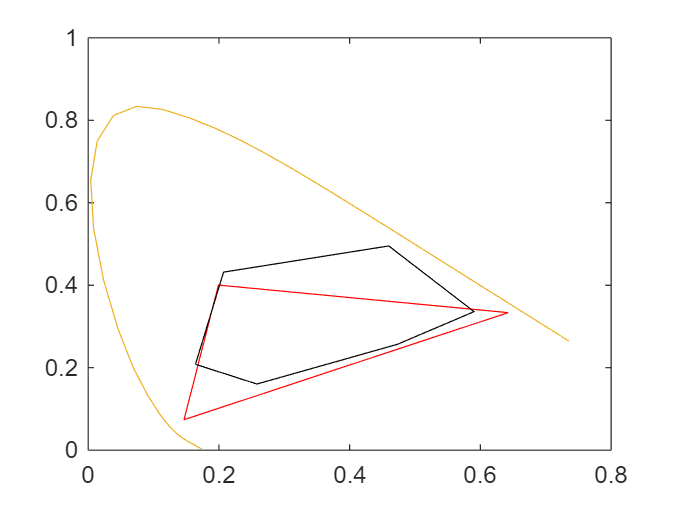

%1
clear
load("Dell.mat")
load("Inkjet.mat")

hold off

plot_chrom(XYZdell,"r") %r, red
plot_chrom(XYZinkjet,"k")%k is black in cmyk

Inkjet covers a somewhat larger area in general but misses some of the reds and blues that dell covers, mainly blue though.

%2.1.1
clear
%Load with imread and immediately convert to double
grayPeppers=im2double(imread("peppers_gray.tif"));
save("grayPeppers","grayPeppers")

%Img resizing
nearestPeppers=imresize(imresize(grayPeppers,0.25,"nearest"),4,"nearest");
bilinearPeppers=imresize(imresize(grayPeppers,0.25,"bilinear"),4,"bilinear");
bicubicPeppers=imresize(imresize(grayPeppers,0.25,"bicubic"),4,"bicubic");

%SNR Calc
"SNR"
snr(grayPeppers,grayPeppers-nearestPeppers)
mysnr(grayPeppers,grayPeppers-nearestPeppers)

snr(grayPeppers,grayPeppers-bilinearPeppers)
mysnr(grayPeppers,grayPeppers-bilinearPeppers)

snr(grayPeppers,grayPeppers-bicubicPeppers)
mysnr(grayPeppers,grayPeppers-bicubicPeppers)

%MSE Calc
"MSE"
immse(grayPeppers,nearestPeppers)
immse(grayPeppers,bilinearPeppers)
immse(grayPeppers,bicubicPeppers)

%Visual comparison
imshow(nearestPeppers)
imshow(bilinearPeppers)
imshow(bicubicPeppers)

Bicubic is visually the best representation.

MSE thinks they're all about the same, but SNR (which is better the higher) would argue it's Bicubic.

%2.1.2
%imThresh=double(grayPeppers>=0.65);
imThresh=double(grayPeppers>=0.5);
save("imThresh","imThresh");
imshow(imThresh)

imDither=double(dither(grayPeppers));
save("imDither","imDither");
imshow(imDither)
"SNR"
snr(grayPeppers,grayPeppers-imDither)
snr(grayPeppers,grayPeppers-imThresh)
"MSE"
immse(grayPeppers,imDither)
immse(grayPeppers,imThresh)

According to mse imdither is about the same as imthresh.

SNR identifies this imdither as a better sowith a higher score.

%2.2
clear
%Load RGB image
colorPeppers=im2double(imread("peppers_color.tif"));
imshow(colorPeppers)

%Half-tone channels by thresholding
htTHColorPeppers=cat(3,double(colorPeppers(:,:,1)>=0.5),double(colorPeppers(:,:,2)>=0.5),double(colorPeppers(:,:,3)>=0.5));
imshow(htTHColorPeppers)

%Dither half-toning
htDTColorPeppers=cat(3,double(dither(colorPeppers(:,:,1))),double(dither(colorPeppers(:,:,2))),double(dither(colorPeppers(:,:,3))));
imshow(htDTColorPeppers)

%Convert to Lab
labPeppers=rgb2lab(colorPeppers);
labhtTHPeppers=rgb2lab(htTHColorPeppers);
labhtDTPeppers=rgb2lab(htDTColorPeppers);
"MSE"
immse(labPeppers,labhtDTPeppers)
immse(labPeppers,labhtTHPeppers)
"SNR"
snr(labPeppers,labPeppers-labhtDTPeppers)
snr(labPeppers,labPeppers-labhtTHPeppers)


diff_REF_CAL1=sqrt((labPeppers(:,:,1)-labhtDTPeppers(:,:,1)).^2+(labPeppers(:,:,2)-labhtDTPeppers(:,:,2)).^2+(labPeppers(:,:,3)-labhtDTPeppers(:,:,3)).^2);
diff_REF_CAL2=sqrt((labPeppers(:,:,1)-labhtTHPeppers(:,:,1)).^2+(labPeppers(:,:,2)-labhtTHPeppers(:,:,2)).^2+(labPeppers(:,:,3)-labhtTHPeppers(:,:,3)).^2);

mean(mean(diff_REF_CAL1))
mean(mean(diff_REF_CAL2))

MSE puts the thresholded image as WILDLY of, sure it's not super accurate but it's definately not THAT bad. SNR puts them as somewhat equal, with dither being slightly better which i would agree on.

%3.1
clear
load("imDither.mat")
load("imThresh.mat")
load("grayPeppers.mat")

ditherNoise=grayPeppers-imDither;
threshNoise=grayPeppers-imThresh;
imshow(imDither)
snr_filter(grayPeppers,ditherNoise)
imshow(imThresh)
snr_filter(grayPeppers,threshNoise)

If higher snr is better then it would correctly identify now that the dither representations is better.

%3.2
clear
colorPeppers=im2double(imread("peppers_color.tif"));
labPeppers=rgb2lab(rgb_filter(colorPeppers));

%Remake the half-toning but now apply filter before Lab
%Half-tone channels by thresholding
htTHColorPeppers=cat(3,double(colorPeppers(:,:,1)>=0.5),double(colorPeppers(:,:,2)>=0.5),double(colorPeppers(:,:,3)>=0.5));
imshow(htTHColorPeppers)

%Dither half-toning
htDTColorPeppers=cat(3,double(dither(colorPeppers(:,:,1))),double(dither(colorPeppers(:,:,2))),double(dither(colorPeppers(:,:,3))));
imshow(htDTColorPeppers)

%Convert to Lab & apply filter
labhtTHPeppers=rgb2lab(rgb_filter(htTHColorPeppers));
labhtDTPeppers=rgb2lab(rgb_filter(htDTColorPeppers));
"Dither"
immse(labhtDTPeppers,labPeppers)
"Threshold"
immse(labhtTHPeppers,labPeppers)

diff_REF_CAL1=sqrt((labPeppers(:,:,1)-labhtDTPeppers(:,:,1)).^2+(labPeppers(:,:,2)-labhtDTPeppers(:,:,2)).^2+(labPeppers(:,:,3)-labhtDTPeppers(:,:,3)).^2);
diff_REF_CAL2=sqrt((labPeppers(:,:,1)-labhtTHPeppers(:,:,1)).^2+(labPeppers(:,:,2)-labhtTHPeppers(:,:,2)).^2+(labPeppers(:,:,3)-labhtTHPeppers(:,:,3)).^2);

mean(mean(diff_REF_CAL1))
mean(mean(diff_REF_CAL2))

MSE still thinks dither is the best representation but it likes it far less than previously.

%4.1 S-CIELab
clear

%Prep basics for S-CIELab
colorPeppers=im2double(imread("peppers_color.tif"));
xyzPeppers=rgb2xyz(colorPeppers);
CIED65=[95.05, 100, 108.9];
d=15.7;         % =40cm
ppi=267;        % pixels per inch for Surface Pro 6
sampPerDegree=ppi*d*tan(pi/180);

%Img resizing
nearestPeppers=rgb2xyz(imresize(imresize(colorPeppers,0.25,"nearest"),4,"nearest"));
bilinearPeppers=rgb2xyz(imresize(imresize(colorPeppers,0.25,"bilinear"),4,"bilinear"));
bicubicPeppers=rgb2xyz(imresize(imresize(colorPeppers,0.25,"bicubic"),4,"bicubic"));

%Compute scielab
scieNearest=scielab(sampPerDegree,xyzPeppers,nearestPeppers,CIED65,'xyz');
scieBilinear=scielab(sampPerDegree,xyzPeppers,bilinearPeppers,CIED65,'xyz');
scieBicubic=scielab(sampPerDegree,xyzPeppers,bicubicPeppers,CIED65,'xyz');

%Get the means
diffNearest=mean(mean(scieNearest));
diffBilinear=mean(mean(scieBilinear));
diffBicubic=mean(mean(scieBicubic));

%Scielab images
imshow(scieNearest)
imshow(scieBilinear)
imshow(scieBicubic)

Bicubic has the lowest mean difference, which affirms the viewable assumption, that bicubic is the better method. When viewing the differences of the images, certain aspects are clearly visible, bilinear which was a blurry result has a lot of contours in the differences image, while bicubic have som minor highfrequency details missing.

%4.2
%Clear and do basic prep
clear
load("colorhalftones.mat")
d=15.7;         % =40cm
ppi=267;        % pixels per inch for Surface Pro 6
sampPerDegree=ppi*d*tan(pi/180);

%Convert all halftone patches to xyz
c1XYZ=rgb2xyz(c1);
c2XYZ=rgb2xyz(c2);
c3XYZ=rgb2xyz(c3);
c4XYZ=rgb2xyz(c4);
c5XYZ=rgb2xyz(c5);

%Use S-CIELab in the secondary method
scieC1=scielab(sampPerDegree,c1XYZ);
scieC2=scielab(sampPerDegree,c2XYZ);
scieC3=scielab(sampPerDegree,c3XYZ);
scieC4=scielab(sampPerDegree,c4XYZ);
scieC5=scielab(sampPerDegree,c5XYZ);

%Show c1 and c2 comparison
imshow(c1)
imshow(c2)
imshow(scieC1)
imshow(scieC2)

std2(scieC1(:,:,1))+std2(scieC1(:,:,2))+std2(scieC1(:,:,3))
std2(scieC2(:,:,1))+std2(scieC2(:,:,2))+std2(scieC2(:,:,3))

Both are just red? Red and kinda grainy, very hard to see though. They seem almost identical, and scielab seems to think so aswell.

imshow(c3)
imshow(c4)
imshow(c5)
imshow(scieC3)
imshow(scieC4)
imshow(scieC5)

They all again are red and a little red, they seem identical, scieC4 is far grainier.

%5 - SSIM
clear

im_ssim=im2double(imread("peppers_gray.tif"));
sizeOfImage=size(im_ssim,1);
a1Distortion=zeros(sizeOfImage);
a2Distortion=a1Distortion;

%Distort a1Distortion
for i=1:sizeOfImage
    if(mod(i,2)==0)
        a1Distortion(i,:)=im_ssim(i,:)+0.1;
    else
        a1Distortion(i,:)=im_ssim(i,:)-0.1;
    end
end

%Distort a2Distortion
for i=1:sizeOfImage
    if(i>(sizeOfImage/2))
        a2Distortion(i,:)=im_ssim(i,:)+0.1;
    else
        a2Distortion(i,:)=im_ssim(i,:)-0.1;
    end
end

snr(im_ssim,im_ssim-a1Distortion)
snr(im_ssim,im_ssim-a2Distortion)

Identical SNR

%Check ssim
imshow(a1Distortion)
imshow(a2Distortion)
[a1val,a1Map]=ssim(im_ssim,a1Distortion);
[a2val,a2Map]=ssim(im_ssim,a2Distortion);

Now they are no longer identical, ssim is able to distinguish their difference.

imshow(a1Map)
imshow(a2Map)

a2's ssim-map is basically the orignial image but with a black line drawn over the middle, while a1 seem to be all the edges in white.

%b distortions
dist1=im_ssim+0.2*(rand(sizeOfImage)-0.5);
f=fspecial('gauss',21,10);
dist2=imfilter(im_ssim,f);

snr(im_ssim,im_ssim-dist1)
snr(im_ssim,im_ssim-dist2)

imshow(dist1)
imshow(dist2)

SNR seem to think dist1 and dist2 are compareable in appearance, but visually are wildly different.

[b1val,b1Map]=ssim(im_ssim,dist1);
[b2val,b2Map]=ssim(im_ssim,dist2);

imshow(b1Map)
imshow(b2Map)

ssim maps are similar except inverted.